# **ESERCITAZIONE ONLINE 0  Introduzione a MATLAB, prof. Giulio Giunta**

## **Le basi**

Matlab  è un ambiente di programmazione per il calcolo scientifico e la visualizzazione grafica. Matlab è anche un linguaggio di programmazione orientato all’approccio detto “a parallelismo sui dati”.

Il prompt è il simbolo >>.

6*7

ans = 42

si è richiesta la valutazione dell’espressione `6*7`; il risultato viene assegnato a una variabile speciale chiamata `ans.`

 exp(sqrt(pi*4))

ans = 34.6365

le espressioni possono contenere parentesi, funzioni `exp` per l’esponenziale, `sqrt`  per la radice quadrata, costanti predefinite ( `pi`  per pi greco)

format long
ans

ans =   34.636488309579761


tutti i dati sono in doppia precisione (circa 16 cifre in base 10); per default vengono visualizzate solo 6 cifre (arrotondamento). Il comando `format long` richiede la visualizzazione di tutte le cifre memorizzate. 

format
ans

ans = 34.6365

Il comando  `format` richiede la visualizzazione sintetica. 

Il valore di una espressione può essere assegnato a una qualunque variabile (nell’esempio `x`). Le variabili non devono essere preventivamente dichiarate:

x = 3*7^5

x = 50421

x = 3*(7^5)

x = 50421

who   


Your variables are:

ans  x    



tutte le variabili utilizzate nella sessione di lavoro possono essere elencate con il comando `who`.

Il valore di una variabile può essere visualizzato semplicemente scrivendo il nome della variabile.

x 

x = 50421

I simboli `+-*/^`, denotano la somma la sottrazione, il prodotto, la divisione e l’elevamento a potenza.

Un aspetto importante di Matlab è la possibilità di operare in modo naturale su matrici e vettori.

x = 10:0.1:11

x =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000


alla variabile `x` è stato assegnato il vettore la cui prima componente (o elemento) è 10, la seconda è 10.1, la terza è 10.2,… fino a 11. Ovvero le componenti differiscono di una quantità costante (detta passo o step), che nell’esempio è 0.1

length(x)

ans = 11

il comando (la function) `length` determina il numero di componenti di un vettore.

Visualizzazione e accesso al valore di una particolare componente di un vettore (si usa un indice in parentesi tonde, a differenza del linguaggio C):

x(1)

ans = 10

ATTENZIONE: l'indice della prima componente di un vettore è 1 (e non 0 come nel linguaggio C).

% x(126)
x(11)

ans = 11

x(length(x))

ans = 11

x(end)

ans = 11

x(end-1) = (x(1)+x(end))/2

x =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.5000   11.0000


z = linspace(0,4*pi,100);

alla variabile `z` è stato assegnato un vettore di 100 componenti. La prima componente è 0, l’ultima è `4*pi`, e le altre sono equispaziate. Il comando definisce una griglia equispaziata di 100 punti nell’intervallo [0,2*pi].

Si noti che il simbolo `;` posto alla fine di una espressione indica che il suo valore non deve essere visualizzato.

length(z)

ans = 100

z(1)

ans = 0

z(100)

ans = 12.5664

z(2)-z(1)

ans = 0.1269

#### Funzioni valutate su un vettore (componente per componente):  

x = linspace(-pi,pi,200); 
y = sin(4*x);
length(y)

ans =    200


la variabile `y` è un vettore le cui componenti sono il valore della funzione seno(4x) calcolata nel valore della corrispondente componente di `x`.

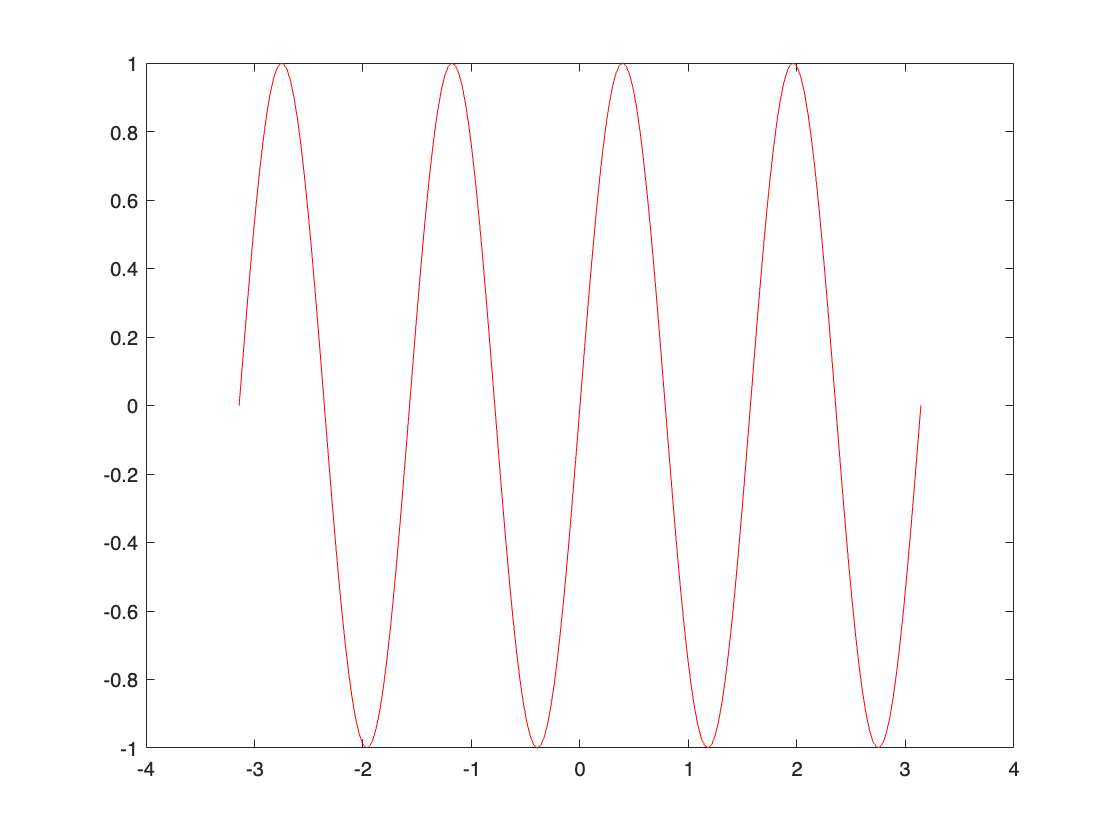

plot(x,y,'r')

Visualizzazione grafica: i punti nel piano le cui ascisse sono in `x` e le cui ordinate sono in `y` vengono connessi mediante una spezzata e visualizzati in figura 1.

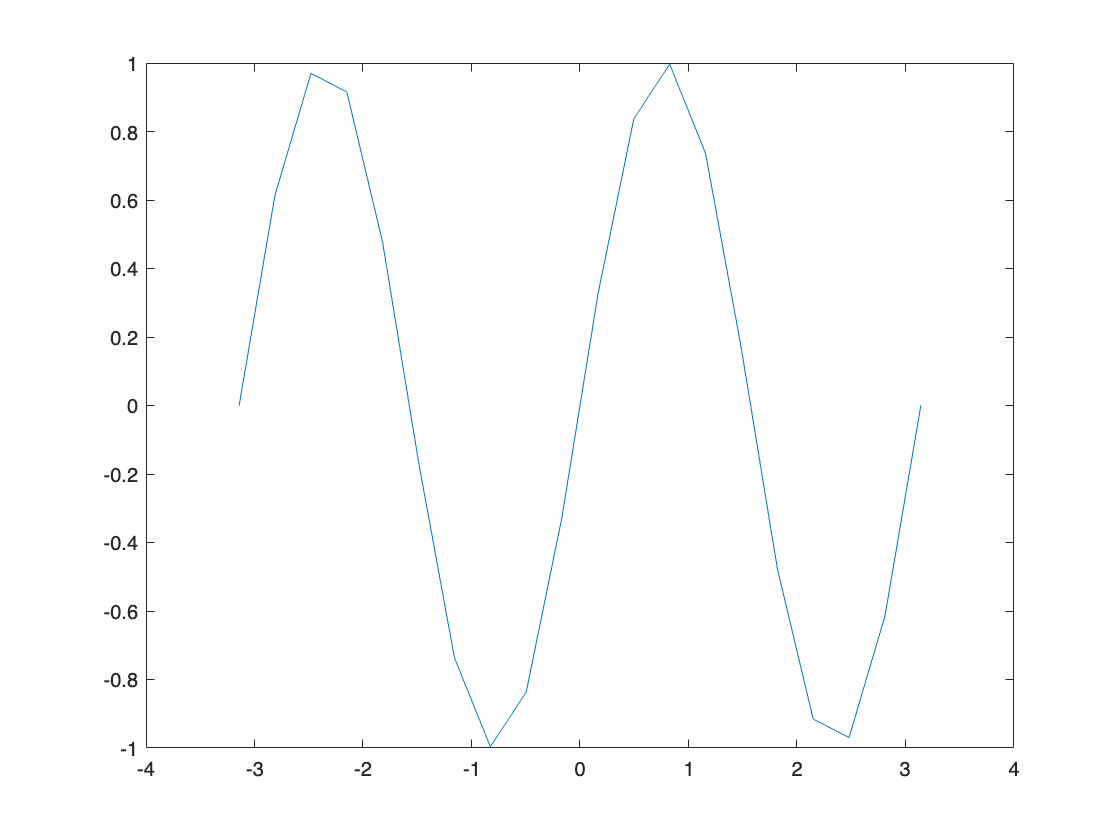

clear
x = linspace(-pi,pi,20);
y = sin(2*x);
plot(x,y)

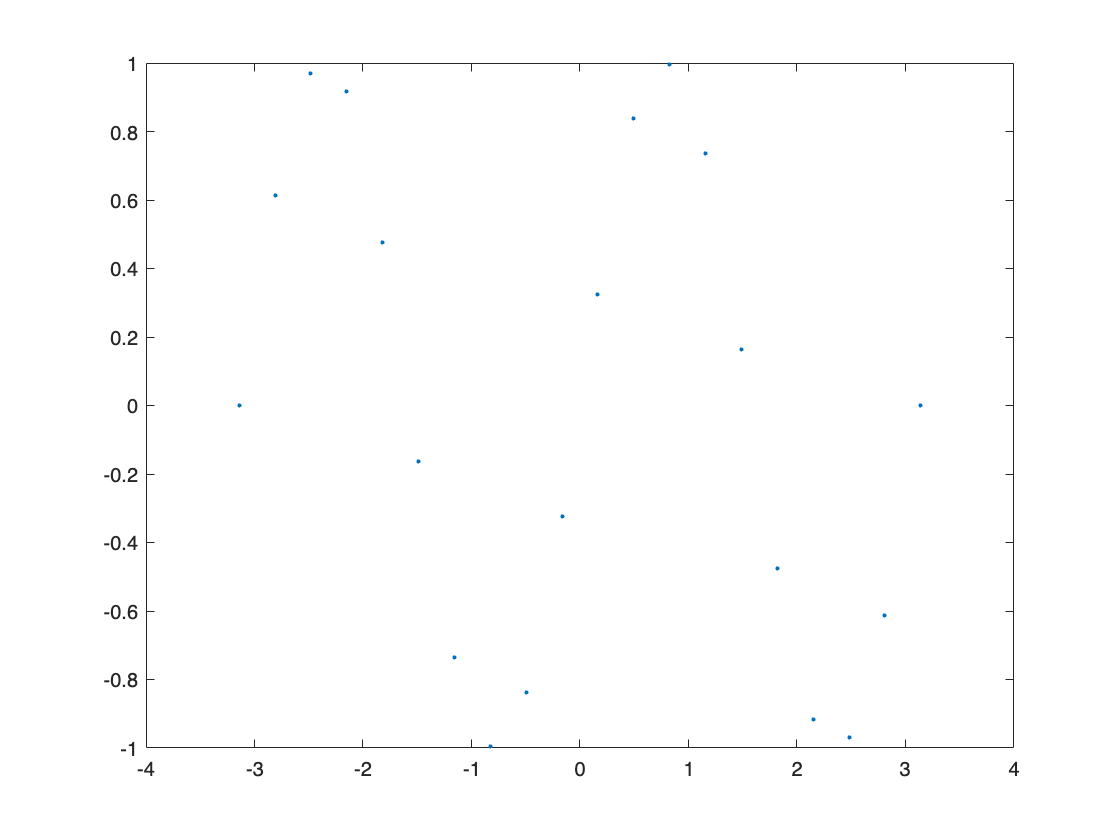

figure(2)
plot(x,y,'.')

Visualizzazione grafica: i punti nel piano le cui ascisse sono in `x` e le cui ordinate sono in `y` vengono visualizzati in figura 2 mediante un cerchietto, senza essere connessi dalla spezzata.

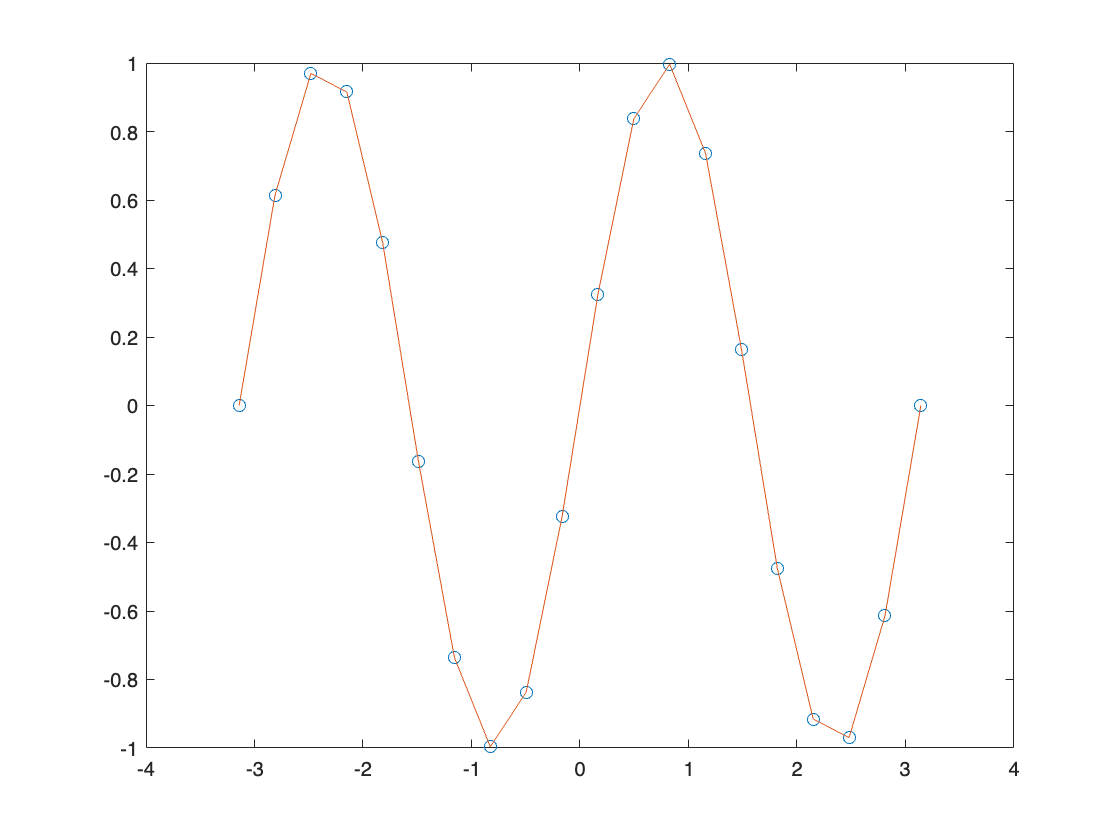

figure(3)
plot(x,y,'o',x,y)

Visualizzazione grafica: i punti nel piano le cui ascisse sono in `x` e le cui ordinate sono in `y` vengono visualizzati in figura 2 mediante un cerchietto; nella stesa figura viene anche visualizzata la spezzata che connette tali punti.

% help plot

Definizione di un vettore per enumerazione delle componenti:

x = [3,7,43]

x =      3     7    43


x'

ans =      3
     7
    43


alla variabile `x` viene assegnato un vettore riga.

y = [5;0;24]

y =      5
     0
    24


alla variabile `y` viene assegnato un vettore colonna.

il prodotto tra un vettore riga e un vettore colonna (stesso numero di componenti) è un numero. L’operazione è detta prodotto scalare:

x*y

ans =         1047


sum(x'.*y)

ans =         1047


Il prodotto tra un vettore colonna e un vettore riga è una matrice. L’operazione è detta prodotto esterno:

y*x

ans =           15          35         215
           0           0           0
          72         168        1032


il  simbolo `' `indica l’operazione di trasposizione:

y=y'

y =      5     0    24


x

x =      3     7    43


Il  simbolo `.* `indica l’operazione di prodotto componente per componente:

z = x.*y

z =           15           0        1032


Esercizio: visualizzare il grafico della funzione “x al quadrato” sul dominio [-1,1].

1) costruzione della griglia sul dominio

x = linspace(-1,1,100);

2) valutazione della funzione “x al quadrato”  sulla griglia (detta anche dominio discreto). I valori sono assegnati alla variabile `y`  che è quindi un vettore di 100 componenti.

y = x.^2;

il  simbolo `.^ `indica l’operazione di potenza componente per componente.

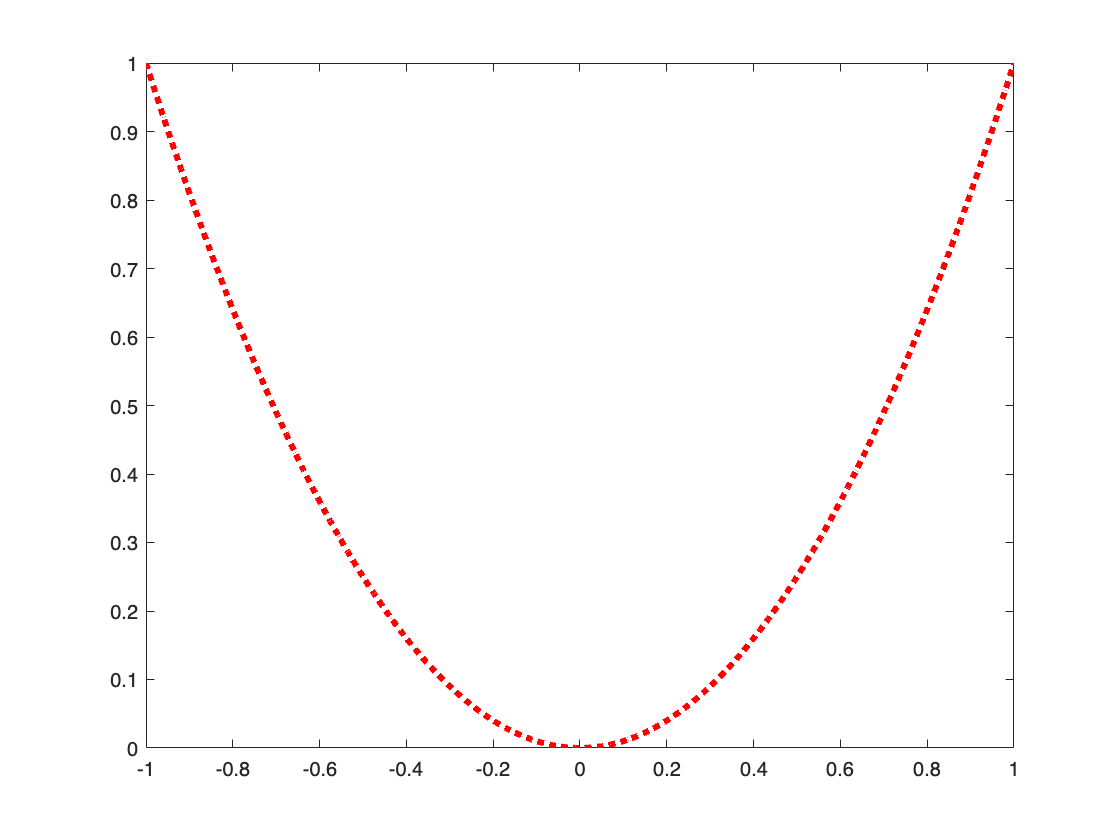

plot(x,y,'r:','linewidth',3)

visualizzazione del grafico.

#### Azioni su vettori e matrici

 A = [3 4 7; 5 0 1;66 2 -6]

A =      3     4     7
     5     0     1
    66     2    -6


alla variabile `A` viene assegnata una matrice di 3   righe e 3 colonne.

Visualizzazione e accesso a un particolare elemento della matrice `A`. Si usa una coppia di indici tra parentesi tonde (altra differenza con il linguaggio C )

ATTENZIONE: gli indici della prima componente di una matrice sono 1,1 (e non 0,0 come nel linguaggio C):

A(1,1)

ans = 3

A(2,2)

ans = 0

A(2,2) = 7

A =      3     4     7
     5     7     1
    66     2    -6


A(end,end)

ans = -6

clear
x = [5 -1 7]

x =      5    -1     7


x=[x(1:2) 100 x(end)]

x =      5    -1   100     7


alla variabile `x` , che è un vettore riga, viene aggiunta una nuova componente.

y = x(2:1:4)

y =     -1   100     7


alla variabile `y` vengono assegnate le componenti di `x`  i cui indici sono indicati dal vettore in parentesi. Ovvero gli indici sono indicati dal vettore  `2:1:4`, cioè sono 2,3,4.

y = x(2:4)

y =     -1   100     7


x(1:2:end)

ans =      5   100


x

x =      5    -1   100     7


z = x([2 1])

z =     -1     5


In questo modo si “invertono” le componenti di un vettore. Osservavate che in Matalb se si `x(espressione) `scrive  , l’espressione all’interno della coppia di parentesi tonde deve essere un vettore che precisa a quali indici si è interessati.

Un vettore può essere definito scrivendo esplicitamente tutte le componenti:

x = [5 -1 7]

x =      5    -1     7


x = x(end:-1:1)

x =      7    -1     5


x = [10 x]

x =     10     7    -1     5


x = [x(1:end/2) 0 x(end/2+1:end)]

x =     10     7     0    -1     5


al vettore viene aggiunta “al centro” una componente (che vale 0) .

 x = x'

x =     10
     7
     0
    -1
     5


x = [x;100]

x =     10
     7
     0
    -1
     5
   100


aggiunta di una componente a un vettore colonna.

 B = [x -x]

B =     10   -10
     7    -7
     0     0
    -1     1
     5    -5
   100  -100


alla variabile `B`  è stata assegnata una matrice di due colonne. La prima colonna è il vettore `x`, la seconda è il vettore `-x `

z = B(1,1:end)

z =     10   -10


alla variabile |z| è stato assegnato il vettore “prima riga di `B` “.

z = B(1,:)

z =     10   -10


si noti l’uso del `:` , che è equivalente a `1:end`

B(:,1)

ans =     10
     7
     0
    -1
     5
   100


è stato selezionato il vettore “prima colonna di `B` “.

B

B =     10   -10
     7    -7
     0     0
    -1     1
     5    -5
   100  -100


B(4:5,:)

ans =     -1     1
     5    -5


è stato selezionato la (sotto)matrice formata dalla “quarta e quinta riga di `B` “.

x

x =     10
     7
     0
    -1
     5
   100


x(5)=[]

x =     10
     7
     0
    -1
   100


x(3:4)=[100 200]

x =     10
     7
   100
   200
   100


sono state eliminate la terza e la quarta componente del vettore `x`.

x([1 3])=[]

x =      7
   200
   100


sono state eliminate la prima e la terza componente del vettore `x`.

Trasposta di una matrice:

B'

ans =     10     7     0    -1     5   100
   -10    -7     0     1    -5  -100


B'.^2

ans =          100          49           0           1          25       10000
         100          49           0           1          25       10000


elevamento al quadrato (operazione componente per componente) di tutte le componenti della matrice `B`.

%B^2

Il quadrato di una matrice è la matrice che si ottiene facendo il prodotto (righe per colonne) della matrice per se stessa. In questo caso (essendo  `B` una matrice non quadrata) il prodotto non è definito.

size(B)

ans =      6     2


il comando (function)  `size`  determina il numero di righe e di colonne di una matrice.

size(B,1)

ans = 6

size(B,2)

ans = 2

#### **Esercizi**

**1 **la function `rand(m,n) `genera una matrice m,n di numeri casuali uniformemente distribuiti in $[0,1]$. Visualizzare il grafico della funzione $sin(4x)$ nell'intervallo $[0,2 \pi]$ in rosso, della funzione $sin(4x)$ con una perturbazione additiva casuale compresa tra 0 e 0.2 (in verde), e della funzione $sin(4x)$ con una perturbazione additiva casuale compresa tra -0.2 e 0.2 (in blu).

**2 **considerare la funzione $sin(4x)$ con una perturbazione additiva casuale compresa tra -0.2 e 0.2 nell'intervallo $[0,2 \pi]$. Utilizzando solo la function `max,` stimare il valore massimo assunto da tale funzione nell'intervallo $[0,2 \pi]$ e il valore dell'ascissa di tale massimo. Visualizzzre il grafico di tale funzione evidenziando con un punto rosso il valore massimo stimato e con un puntino blu l'ascissa del massimo stimato.

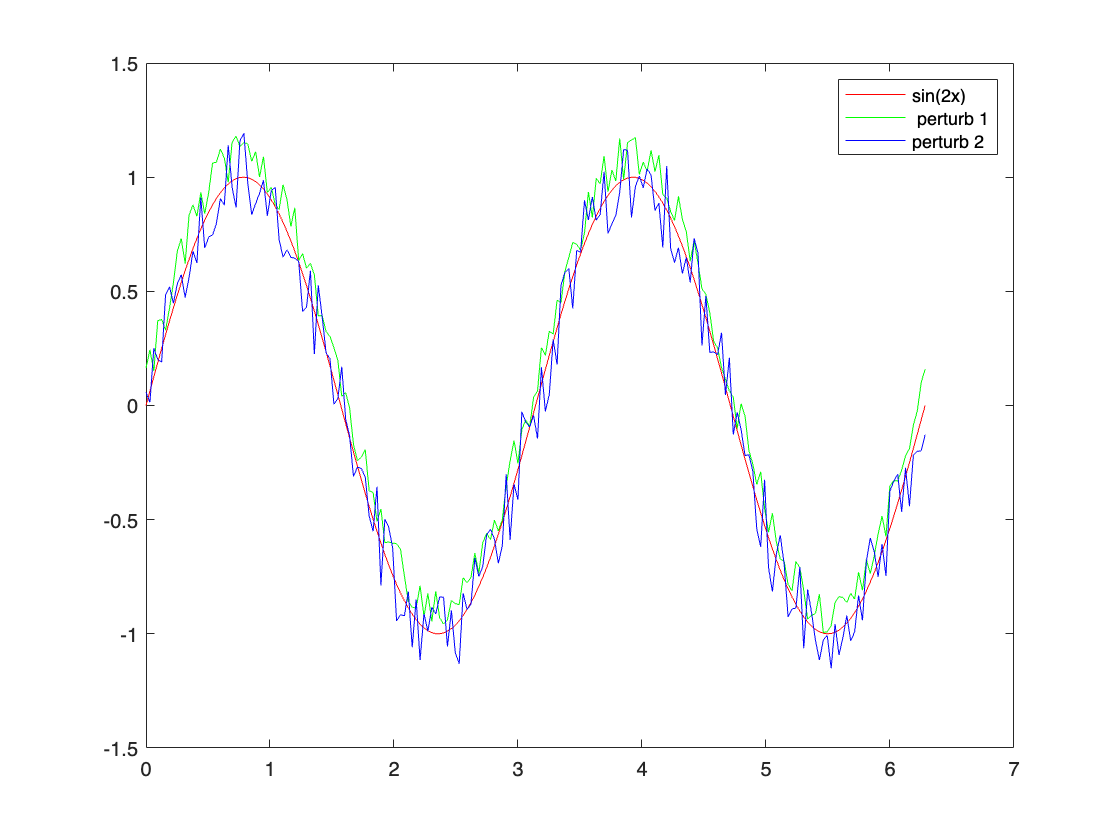

% Esercizio 1
x = linspace(0,2*pi,200);
y = sin(2*x);
yp1 = y + 0.2*rand(1,length(x));
yp2 = y -0.2+0.4*rand(1,length(x));
figure(1)
plot(x,y,'r',x,yp1,'g',x,yp2,'b')
legend('sin(2x)',' perturb 1','perturb 2')

% Esercizio 2
x = linspace(0,2*pi,200);
y = sin(2*x) - 0.2+0.4*rand(1,length(x));
[valmax,indmax] = max(y);
argmax = x(indmax);
sprintf(' valore max = %f \n arg (ascissa) max = %f',valmax,argmax)

ans =     ' valore max = 1.175389 
      arg (ascissa) max = 4.009872'


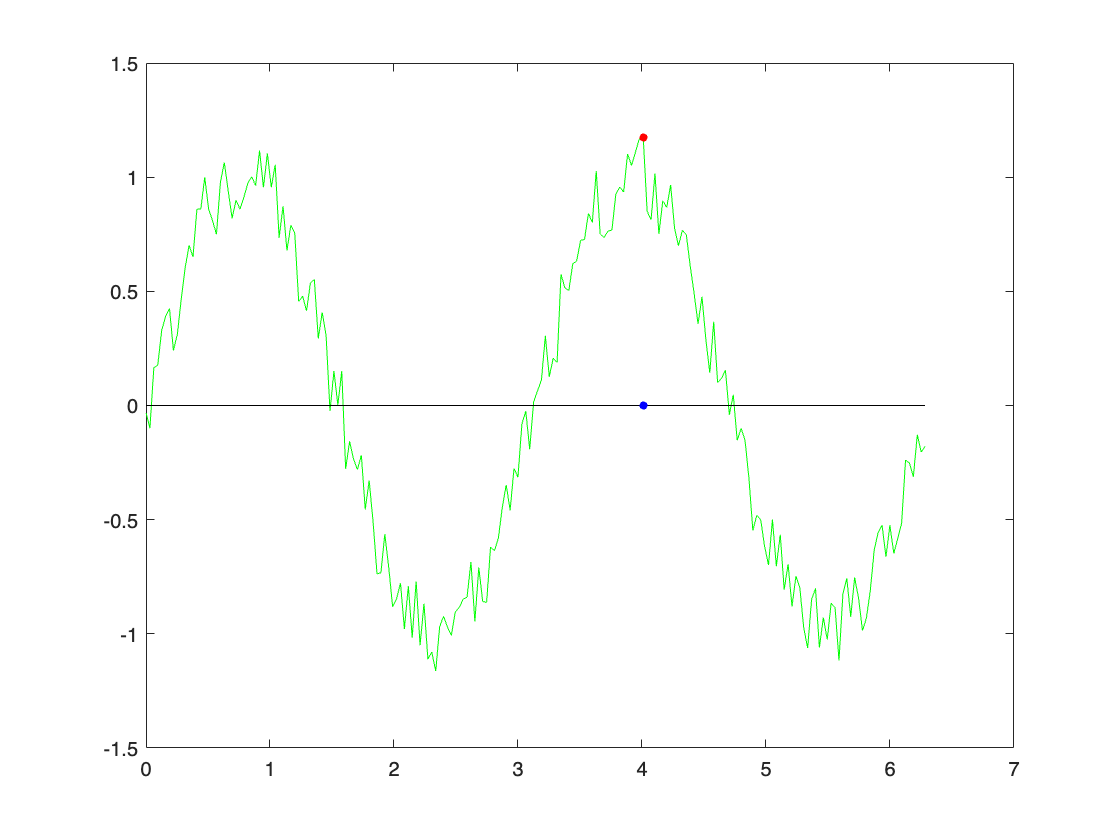

figure(2)
plot(x,y,'g',[min(x) max(x)],[0 0],'k',argmax,valmax,'.r',argmax,0,'.b','markersize',12)

#### rappresentazione f-p

Esperimento dell'epsilon macchina:

clear
	numero = 1.0;
	uno = 1.0;
	cont = 0;
	sum = uno + numero;
	while sum > uno
		numero = numero/2; cont = cont + 1; 
		sum = uno + numero;
	end
	numero = numero*2;
	sprintf('numero = %24.16e \n numero divisioni = %d\n',numero,cont)

ans =     'numero =   2.2204460492503131e-16 
      numero divisioni = 53
     '


eps di Matlab, cioè la differenza tra il numero fp succesivo a 1 e 1:

format long
eps

ans =      2.220446049250313e-16


2^(-52)

ans =      2.220446049250313e-16


1+eps

ans =    1.000000000000000


1+eps/4

ans =      1


rappresentazione di numeri in formato esadecimale (la "fotografia" del contenuto della cella di memoria):

format hex
0

ans =    0000000000000000


1

ans =    3ff0000000000000


1+eps

ans =    3ff0000000000001


1+eps/2

ans =    3ff0000000000000


1+eps/2+eps/2

ans =    3ff0000000000000


1+2^(-52)

ans =    3ff0000000000001


1+2^(-53)

ans =    3ff0000000000000


1+(eps/2+eps/2)

ans =    3ff0000000000001


1+(eps/2+eps/4)

ans =    3ff0000000000001


1+(eps/2+eps/10)

ans =    3ff0000000000001


Alcuni numeri fp speciali:

max=(2-2^(-52))*2^1023

max =    7fefffffffffffff


realmax

ans =    7fefffffffffffff


2*max

ans =    7ff0000000000000


max+1

ans =    7fefffffffffffff


max+eps*max

ans =    7ff0000000000000


format long
3.234e12+(0.1*eps*3.234e12)

ans =      3.234000000000000e+12


7.734e-34+(0.1*eps*7.734e-34)

ans =      7.734000000000000e-34


La function eps(x) restituisce la distanza tra `x` e il numero fp successivo a x:

eps(10)

ans =      1.776356839400250e-15


Pertanto le due seguenti istruzioni sono equivalenti

3.234e12+(0.1*eps(3.234e12))

ans =      3.234000000000000e+12


3.234e12+(0.1*eps*3.234e12)

ans =      3.234000000000000e+12


7.734e-34+(0.1*eps(7.734e-34))

ans =      7.734000000000000e-34


format long
1000+0.2*eps(1000)

ans =         1000
